## Problem 2

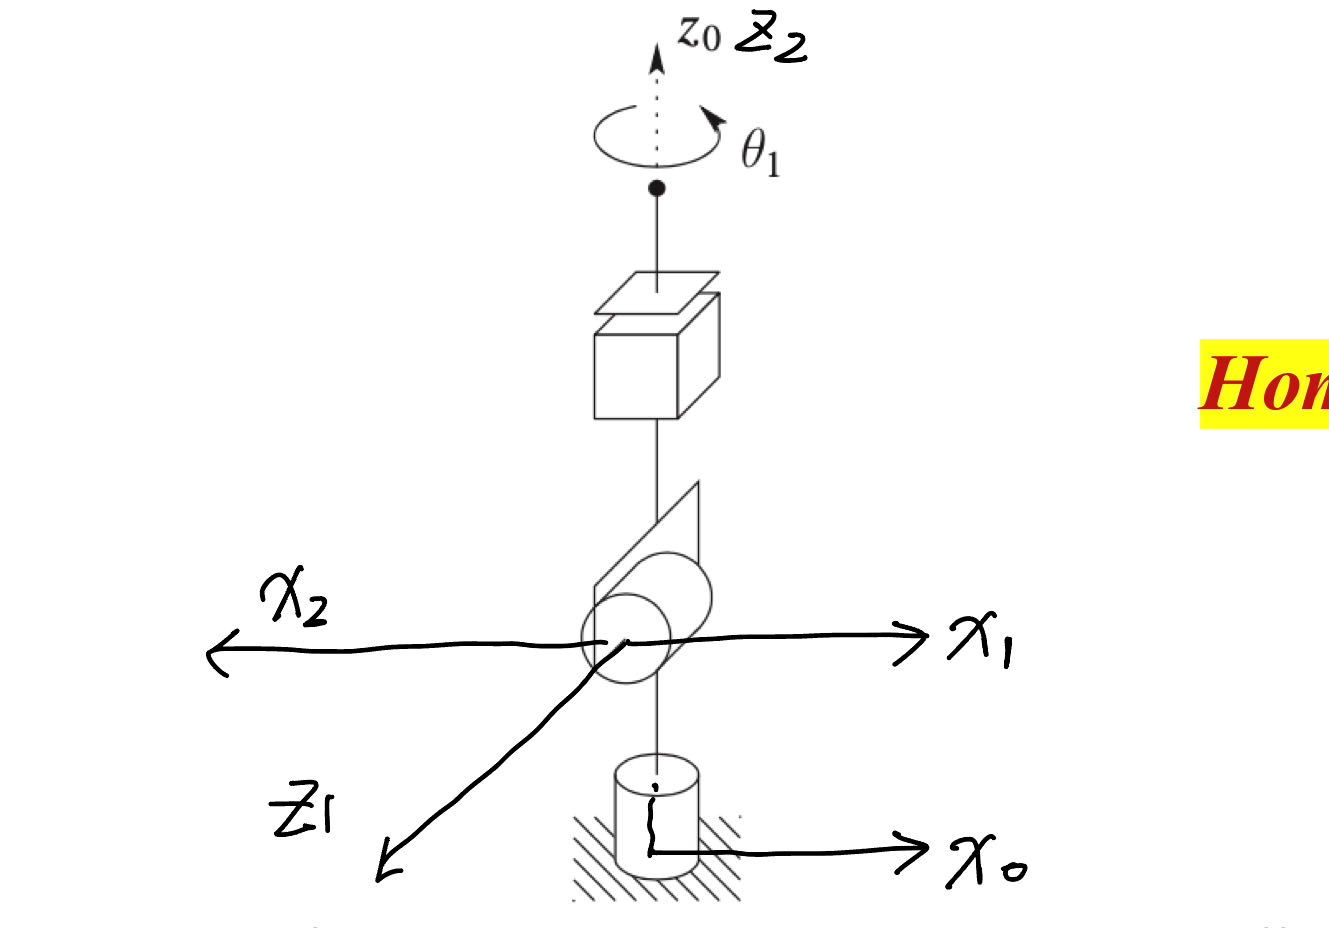

         theta     d    alpha    a

1       theta1   l1      90    0

2       theta2   l2     -90     0

3        0          d3       0      0

Define all the variables(theta1,theta2,d3 are joint variables):

clc,clear


theta1=pi/6;
theta2=pi/3;
l1=3;
l2=4;
d3=2;

[index,theta1_array,dtheta1_array,ddtheta1_array]=traj_poly3(0,pi,5,100);

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


[index,theta2_array,dtheta2_array,ddtheta2_array]=traj_poly3(0,pi,5,100);

index =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


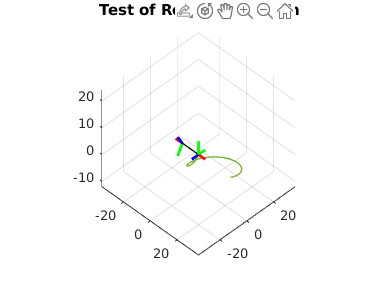



x_end=[];
y_end=[];
z_end=[];

for i=index
theta1=theta1_array(i);
theta2=theta2_array(i);


pause(0.01)
theta_array=[theta1,theta2];
d_array=[0,0];
alpha_array=[-45,45];
a_array=[12,12];

H=[];


for k=1:length(theta_array)
    T1=[cos(theta_array(k)),-sin(theta_array(k)),0,0;
        sin(theta_array(k)),cos(theta_array(k)),0,0;
        0,0,1,0
        0,0,0,1];
 
    I=eye(3);
    pd=transpose([0,0,d_array(k)]);
    T2=[I,pd;
        0,0,0,1];

    pa=transpose([a_array(k),0,0]);
    T3=[I,pa;
        0,0,0,1];

    T4=[1,0,0,0;
        0,cosd(alpha_array(k)),-sind(alpha_array(k)),0;
        0,sind(alpha_array(k)),cosd(alpha_array(k)),0;
        0,0,0,1];
 
    H_current=T1*T2*T3*T4;
    H=[H,H_current];
end

x0=[5,0,0,1].';
y0=[0,5,0,1].';
z0=[0,0,5,1].';
joints_number=length(H)/4;
joints=[0;0;0];


plot3([0,x0(1)],[0,x0(2)],[0,x0(3)],LineWidth=2,Color='r')
hold on
plot3([0,y0(1)],[0,y0(2)],[0,y0(3)],LineWidth=2,Color='g')
plot3([0,z0(1)],[0,z0(2)],[0,z0(3)],LineWidth=2,Color='b')



for k=1:joints_number
    H_temp=eye(4);
    for m=1:k
        H_temp=H_temp*H(:,4*(m-1)+1:4*m);
    end

    joints=[joints,H_temp(1:3,4)];
    
    new_x=H_temp*x0;
    new_y=H_temp*y0;
    new_z=H_temp*z0;
    
    plot3([H_temp(1,4),new_x(1)],[H_temp(2,4),new_x(2)],[H_temp(3,4),new_x(3)],Color='r',LineWidth=2),grid
    hold on
    plot3([H_temp(1,4),new_y(1)],[H_temp(2,4),new_y(2)],[H_temp(3,4),new_y(3)],Color='g',LineWidth=2),grid
    plot3([H_temp(1,4),new_z(1)],[H_temp(2,4),new_z(2)],[H_temp(3,4),new_z(3)],Color='b',LineWidth=2),grid
    axis square
    xlim([-3*12,3*12]);
    ylim([-3*12,3*12]);
    zlim([-12,2*12]);

    if k==joints_number
        x_end=[x_end H_temp(1,4)];
        y_end=[y_end H_temp(2,4)];
        z_end=[z_end H_temp(3,4)];
    end
        
end

for n=1:length(joints)-1
    plot3([joints(1,n),joints(1,n+1)],[joints(2,n),joints(2,n+1)],[joints(3,n),joints(3,n+1)],Color='k',LineWidth=1,LineStyle='--'),grid
end 

plot3(x_end,y_end,z_end,LineWidth=1)

view([45 45])
title('Test of Robot Animation')
grid
hold off
end